# Ideal case code

## Import data (from camera 1)

%%% Imports data
Dataset = 'Ideal_Case';
Camera = 'cam1_1.mat';

camData = importCamData(Dataset,Camera);


## Camera 1

### Shows uncropped and cropped frame in colour

%%% Shows uncropped and cropped frame in colour
frame = 1

frame = 1

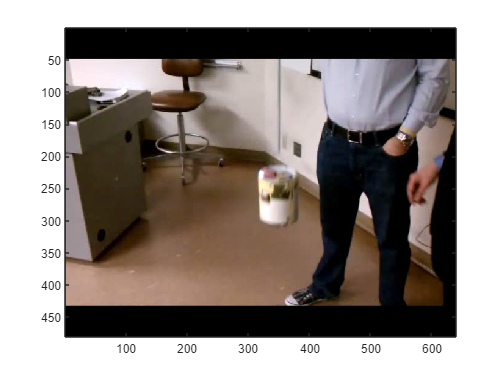


camImage = image(camData.vidFrames1_1(:,:,:,frame));

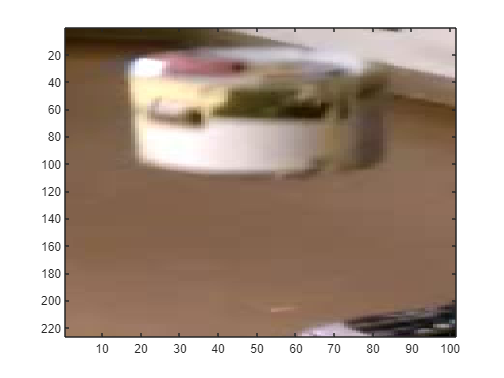

width = 300:400;
height = 200:425;
croppedFrame = camData.vidFrames1_1(height,width,:,frame);
croppedFrame1 = camData.vidFrames1_1(height,width,:,1);
camImageCropped = image(croppedFrame);

### Shows frame of grayscale image

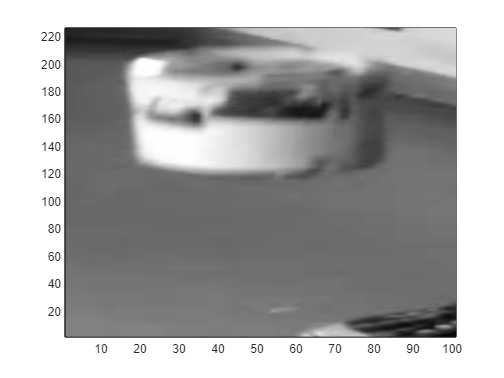

%%% Shows a frame from any camera as a grayscale colourmap (to locate
%%% locations of particular points

%%% Modified from: Data-Driven Modeling & Scientific Computation: 
%%% Methods for Complex Systems & Big Data 
%%% by J. NATHAN KUTZ


a = flipud( double( rgb2gray( camData.vidFrames1_1(height,width,:,1) )));
% a = flipud( double( rgb2gray( camData_2.vidFrames2_1(height_2,width_2,:,1) )));
% a = flipud( double( rgb2gray( camData_3.vidFrames3_1(height_3,width_3,:,1) )));

% x = 1:640;
% y = 1:480;
% [X,Y]=meshgrid(x,y);
% pcolor(X,Y,a)
pcolor(a)
shading interp
colormap("gray")

% set(gca,'Xtick',[],'Ytick',[],'Ztick',[])


### Finds and shows cap pixels (using both methods)

%%% Finds and shows cap pixels
x = 22;
y = 197;


r = croppedFrame1(end-y,x,1)

r = uint8
249

g = croppedFrame1(end-y,x,2)

g = uint8
255

b = croppedFrame1(end-y,x,3)

b = uint8
253

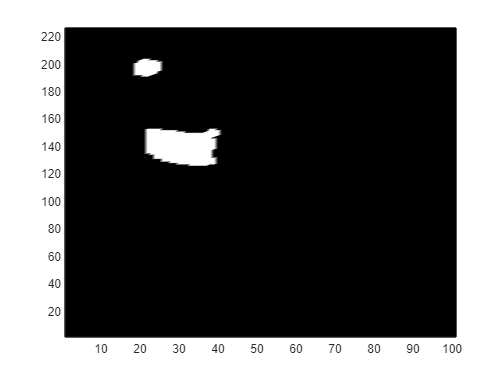


d = 20;
cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));

pcolor(flipud(cap_Pixels))
shading interp
colormap("gray")

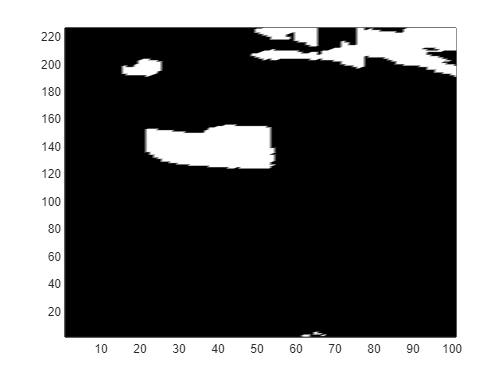


cap_Pixels_2 = getCapPixelsBright(croppedFrame,d);

pcolor(flipud(cap_Pixels_2))
shading interp
colormap("gray")

### Finds x and y coordinate of average of cap pixels

%%% Finds x and y coordinate of average of cap pixels
bounds = Boundaries(cap_Pixels)

bounds = 202

[top,bottom,left,right] = Boundaries(cap_Pixels)

top = 202

bottom = 125

left = 19

right = 40


[x,y] = centre(top,bottom,left,right)

x = 29.5000

y = 163.5000

[x_avg,y_avg] = centre_avg(cap_Pixels)

x_avg = 29.4735

y_avg = 147.1918

### Finds position of cap and stores it into a vector

%%% Finds position of cap and stores it into a vector
numFrames = size(camData.vidFrames1_1(1,1,1,:),4);
width = 300:400;
height = 200:425;
croppedFrame1 = camData.vidFrames1_1(height,width,:,1);

x = 22;
y = 197;
d = 20;

X_0 = zeros(1,numFrames);
Y_0 = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData.vidFrames1_1(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X_0(i) = x_avg;
    Y_0(i) = y_avg;
end

X_0

X_0 =    29.4735   29.3326   29.2623   29.3360   29.3306   29.3306   29.3306   29.3306   32.9406   34.8804   34.9306   33.2451   33.2544   32.2563   32.2579   31.6225   30.8534   30.8344   30.5163   30.5209   30.0099   30.0476   28.8054   28.7107   28.7218   31.9036   32.0434   33.7573   33.7162   34.9244   34.3037   34.3088   31.3724   31.4217   27.3066   27.3789   27.8837   28.3228   28.3516   28.6404   28.6303   28.8011   28.7721   29.5556   29.6714   29.6776   30.2056   30.2343   33.3731   33.2343


Y_0

Y_0 =   147.1918  147.2141  147.5656  147.4338  147.4796  147.4796  147.4796  147.4796  151.6327  152.6360  152.7326  148.9275  148.9941  141.4727  141.4570  131.9117  116.8147  116.8989  100.9465  100.9907   84.8251   84.5589   67.6865   51.6336   51.7355   40.2081   40.0714   34.5528   34.6464   33.1113   36.6370   36.7765   43.5944   43.4848   53.1977   53.1083   68.2382   86.0000   85.8732  102.0758  102.0196  116.8925  117.0027  129.5455  140.5610  140.6612  143.7684  143.9349  149.6307  149.2838


### Plots X and Y for camera 1

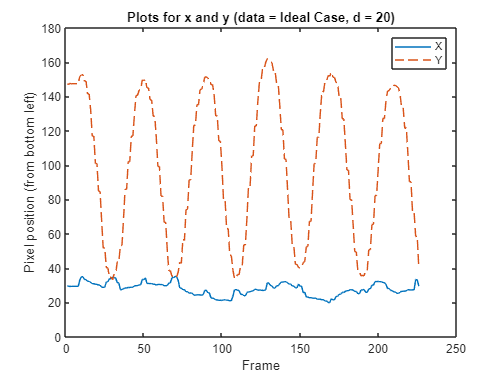

%%% Plots X and Y
plot(X_0)
title('Plots for x and y (data = Ideal Case, d = 20)')
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y_0,'--')
legend('X','Y')
hold off

### Finds and plots X and Y for camera 1 for any d (with function that uses initial position)

%%% Finds and plots X and Y for any d (with function)
width = 300:400;
height = 200:425;
x = 22;
y = 197;
d1 = 50;

[X_11,Y_11] = getXY(camData.vidFrames1_1,width,height,x,y,d1)

X_11 =    51.9483   51.9776   52.5358   52.3875   52.3679   52.3087   52.3679   52.3087   53.3088   53.3887   53.3810   54.8036   54.7981   54.0408   54.1145   51.8467   52.7738   52.7996   52.7543   52.8073   53.2824   53.2221   53.5518   52.9817   52.9035   53.0894   52.8658   52.3127   52.3912   52.7687   51.7176   51.7828   52.5224   52.4334   52.3676   52.2697   51.9071   51.4311   51.4909   50.6768   50.6937   51.6508   51.5398   52.1563   52.8641   53.0574   51.8717   51.7081   52.0643   51.9291


Y_11 =   170.4417  170.4552  170.4759  170.4551  170.4432  170.4159  170.4432  170.4159  173.1658  172.3810  172.4150  171.2095  171.1370  163.2556  163.3344  155.3196  146.4852  146.5912  137.2317  137.4267  127.9432  127.7112  118.0657  106.0033  105.6930   98.8317   98.3176   92.7013   92.9675   91.5764   91.4878   91.8592   99.3178   99.1377  107.3892  107.2946  115.5731  126.4742  126.2424  134.9650  134.7717  146.4249  146.4821  154.3854  162.8454  162.9820  168.6539  168.4962  170.1522  170.1228


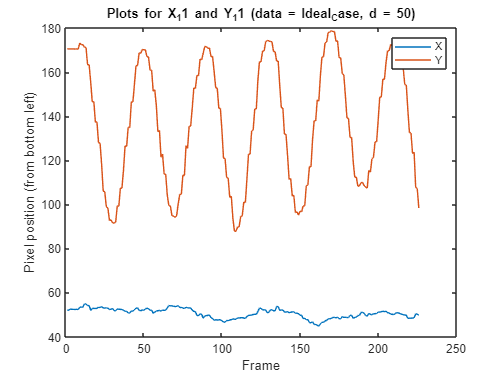

% X_11 = X_11+width(1);
% Y_11 = Y_11+height(1);

plotXY(X_11,Y_11,d1,Dataset)

### Finds and plots X and Y for camera 1 for any d (with function that uses brightness)

%%% Finds and plots X and Y for any d (with function)
width = 300:400;
height = 200:425;
d2 = 50;

[X_12,Y_12] = getXYBright(camData.vidFrames1_1,width,height,d2)

X_12 =    45.0836   45.4077   45.9478   46.3309   46.3171   46.3507   46.3171   46.3507   44.8744   44.4832   44.4132   45.7679   45.7884   46.3547   46.3535   45.3389   45.1482   44.9661   44.4330   44.5662   43.6248   43.5851   43.8722   44.1472   43.9736   42.6394   42.5773   41.7956   41.7989   42.5135   42.7434   42.8783   43.3478   43.3326   43.6908   43.5473   43.4420   44.3726   44.5168   45.7160   45.7339   44.2574   43.8650   46.7425   48.0629   47.8728   46.3709   46.3290   44.6443   44.4859


Y_12 =   139.2498  140.0775  140.7959  141.0343  141.0733  141.0577  141.0733  141.0577  138.6531  137.5131  137.4104  138.1269  138.3597  133.4505  133.1377  127.6197  122.6278  122.4928  114.8908  115.0978  107.2657  107.1183  100.6009   95.0681   94.6229   88.7375   88.5611   84.9842   84.9265   81.1585   83.5758   83.6688   90.1505   90.2382   96.1513   96.2813  102.1296  109.1599  109.2096  118.0716  117.9539  124.4111  123.8266  131.0681  138.7052  138.1392  141.2370  141.0755  140.0702  139.8135


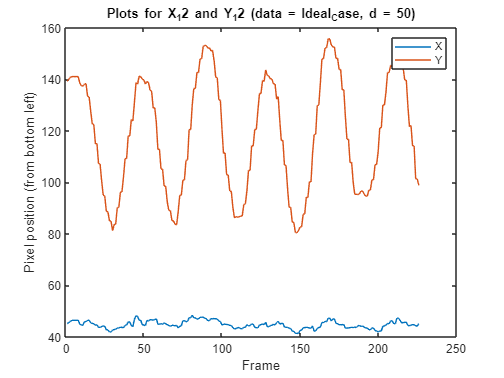


plotXY(X_12,Y_12,d2,Dataset)

## Camera 2

### Imports data

%%% Imports data from second camera
Camera_2 = 'cam2_1.mat';

camData_2 = importCamData(Dataset,Camera_2);


### Shows uncropped and cropped frame in colour

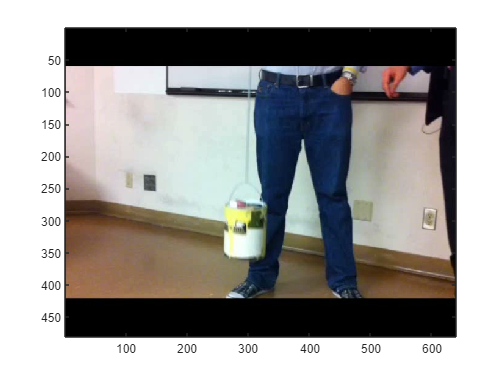

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_2 = 1;

camImage_2 = image(camData_2.vidFrames2_1(:,:,:,frame_2));

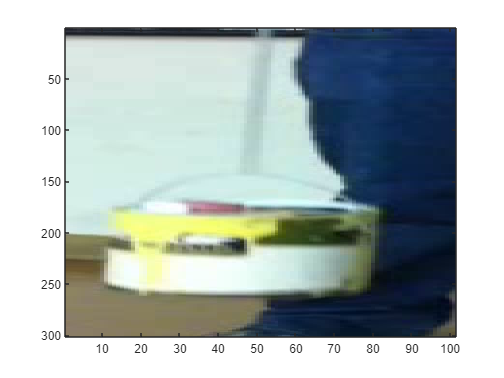

width_2 = 250:350;
height_2 = 100:400;
croppedFrame_2 = camData_2.vidFrames2_1(height_2,width_2,:,frame_2);
camImageCropped_2 = image(croppedFrame_2);

### Finds and plots X and Y for camera 2 (using initial position)

%%% Finds and plots X and Y for camera 2
width_2 = 250:350;
height_2 = 100:400;
x_2 = 26;
y_2 = 126;
d1_2 = 50;

[X_21,Y_21] = getXY(camData_2.vidFrames2_1,width_2,height_2,x_2,y_2,d1_2)

X_21 =    30.1551   30.1678   29.9124   30.1125   29.0046   27.7589   27.7829   27.4185   26.7393   26.8442   27.6703   27.6809   29.0956   29.8179   29.8532   30.3053   30.2869   30.3986   30.9556   31.3311   30.3037   30.2856   29.2114   29.0983   28.7317   27.6847   27.6355   26.7153   26.7484   26.3485   26.7143   26.6675   27.1346   27.2823   27.8533   28.0863   28.1356   28.4726   28.7039   28.8459   29.9931   30.0274   29.9937   30.2418   29.8072   29.3369   29.2681   28.4679   28.3660   28.7008


Y_21 =   181.1124  181.3118  183.9812  187.4471  191.8866  198.1744  198.2571  202.9943  201.0056  195.1737  188.3425  188.3232  182.9480  179.1163  175.3906  172.3646  172.4209  172.6031  172.5435  172.5105  173.6515  173.7638  172.6272  174.3451  178.2067  182.9553  182.9432  188.6720  196.2899  205.0864  203.2290  203.1706  197.8555  191.6156  186.2425  182.6310  182.6814  180.6994  179.9489  182.2330  184.4970  184.4363  187.5068  190.8912  196.2925  200.3301  200.3004  204.5418  205.5911  200.3443


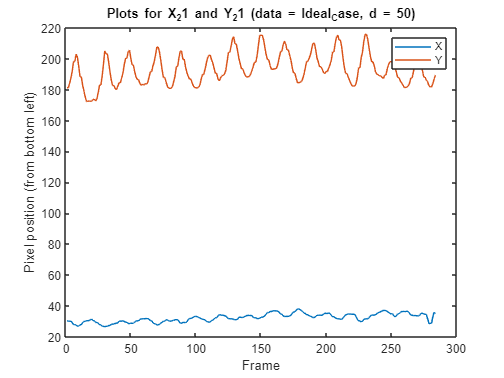


plotXY(X_21,Y_21,d1_2,Dataset)

### Finds and plots X and Y for camera 2 (using brightness)

%%% Finds and plots X and Y for camera 2
width_2 = 250:350;
height_2 = 100:400;
d2_2 = 50;

[X_22,Y_22] = getXYBright(camData_2.vidFrames2_1,width_2,height_2,d2_2)

X_22 =    45.8068   45.8065   46.3654   46.2107   46.4886   47.5919   47.4414   47.7031   46.6992   47.8225   47.9811   48.0124   48.0737   46.9979   46.9162   47.0742   46.7694   46.4228   47.5635   46.5807   46.6352   46.6544   47.6721   49.4696   48.8874   48.4432   48.3998   49.4726   49.8229   50.4867   49.5925   49.5897   49.2046   49.4414   48.6030   47.8630   47.9189   47.8662   47.8493   47.6653   48.4729   48.4837   48.3394   48.8227   48.3771   48.8181   48.7587   49.4656   49.7339   48.7199


Y_22 =   173.0921  173.0626  174.0364  176.3312  178.9742  179.9062  180.0817  182.1309  181.4291  177.7863  176.9902  176.9307  175.1554  174.8284  172.5821  171.9268  172.0369  172.6202  171.2729  171.7353  171.7787  171.8842  170.5314  170.3872  172.0298  174.7269  174.7841  177.2478  180.8975  184.5212  183.9471  183.8483  180.7285  176.7817  174.5098  172.7449  172.4079  170.8811  170.2459  171.7816  173.8590  173.7980  175.5723  178.5235  181.8006  183.3600  183.4107  184.2005  185.3825  184.0331


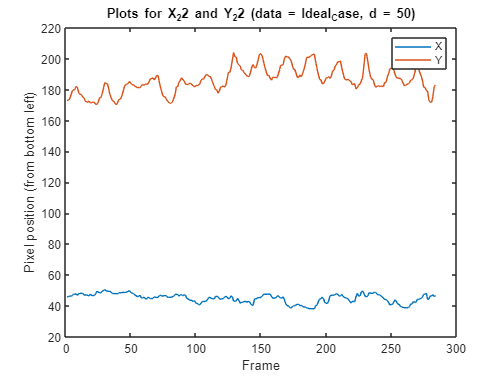


plotXY(X_22,Y_22,d2_2,Dataset)

## Camera 3

### Import data

%%% Imports data from third camera
Camera_3 = 'cam3_1.mat';

camData_3 = importCamData(Dataset,Camera_3);


### Shows uncropped and cropped frame in colour

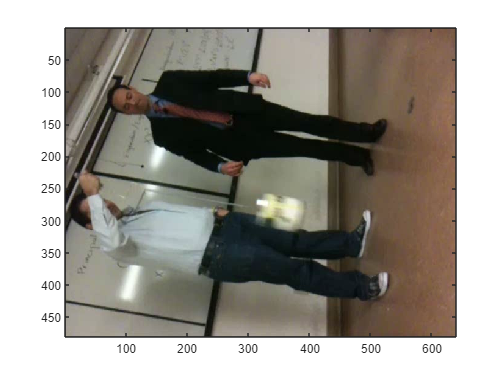

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_3 = 1;

camImage_3 = image(camData_3.vidFrames3_1(:,:,:,frame_3));

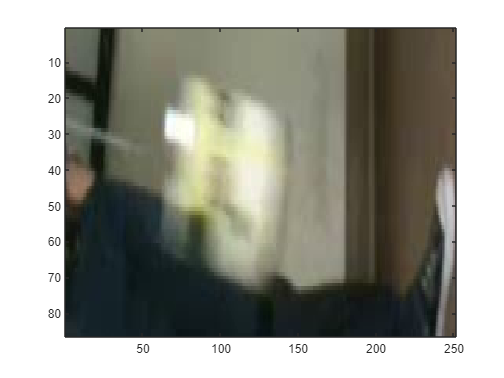

width_3 = 250:500;
height_3 = 245:330;
croppedFrame_3 = camData_3.vidFrames3_1(height_3,width_3,:,frame_3);
camImageCropped_3 = image(croppedFrame_3);

### Finds and plots X and Y for camera 3 (using initial position)

%%% Finds and plots X and Y for camera 3
width_3 = 250:500;
height_3 = 245:330;
x_3 = 73;
y_3 = 59;
d1_3 = 50;

[X_31,Y_31] = getXY(camData_3.vidFrames3_1,width_3,height_3,x_3,y_3,d1_3)

X_31 =   109.8275  109.7992   97.3656   97.6186   87.7212   87.8525   81.0525   79.3957   79.6708   80.4122   80.5599   83.5765   83.7542   90.9776  102.5896  102.7197  118.2135  118.0279  133.8065  133.6620  152.8677  169.5474  169.5517  184.4226  184.4883  195.6843  195.7616  202.8801  206.8919  206.9179  203.1365  203.0958  196.7462  196.8375  184.8597  168.9552  168.8743  152.8952  152.9803  136.9234  136.7732  121.8405  109.3653  109.4342   99.2390   99.0486   93.7537   93.5886   90.1388   90.5952


Y_31 =    50.6417   50.7001   53.7092   53.6098   55.4712   55.4680   57.1109   57.5431   57.3937   57.2854   57.3170   56.9039   56.8425   56.4035   55.9170   55.8682   53.9662   53.9066   52.4874   52.4729   50.4252   48.5461   48.5568   45.1762   44.8826   43.2796   43.1896   40.6777   38.1040   37.6728   38.5510   38.5219   40.7355   40.7232   43.5418   45.7549   46.0321   49.1436   49.1376   50.7229   50.8650   54.1271   54.9564   54.8251   57.0772   56.5599   57.7331   57.7557   56.9143   57.3140


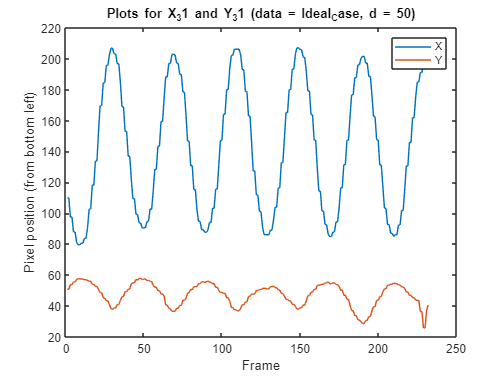


plotXY(X_31,Y_31,d1_3,Dataset)

### Finds and plots X and Y for camera 3 (using brightness)

%%% Finds and plots X and Y for camera 3
width_3 = 250:500;
height_3 = 245:330;
d2_3 = 50;

[X_32,Y_32] = getXYBright(camData_3.vidFrames3_1,width_3,height_3,d2_3)

X_32 =   155.6123  155.6240  155.9327  156.0936  152.2611  152.3017  152.4402  151.6357  151.6364  152.7075  152.7307  152.5179  152.5951  153.2298  158.4088  158.3097  156.8622  156.8913  153.4860  153.6711  149.1039  141.7279  141.4418  134.6967  134.6278  128.4638  128.3488  126.9268  125.8836  125.7405  126.3776  126.3709  128.8842  128.7520  136.3027  142.6304  142.6504  149.9065  150.1706  155.0598  155.0872  159.0237  160.3650  160.2879  157.0223  156.8621  155.3726  155.6894  155.9864  154.8790


Y_32 =    50.1292   50.1333   50.4762   50.3832   50.1923   50.1998   50.2141   50.4046   50.4003   50.4593   50.4285   50.2247   50.1951   50.3911   51.1836   51.1979   51.6999   51.6743   52.3097   52.3113   52.8576   53.9761   54.0519   54.4286   54.3953   55.4799   55.4832   55.0305   54.5418   54.5614   54.8059   54.7784   54.7005   54.7867   53.7733   53.0242   53.1510   52.6397   52.5354   51.9023   51.8596   51.6620   51.1108   51.0775   51.0066   50.9878   50.8601   50.9665   50.7666   51.0616


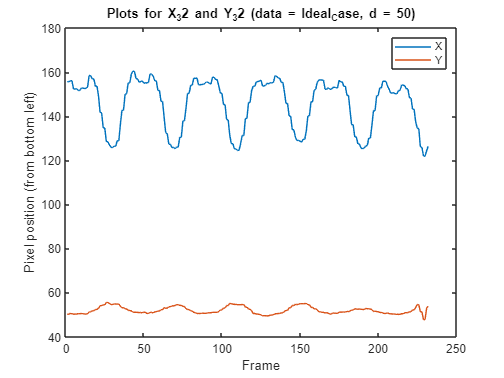


plotXY(X_32,Y_32,d2_3,Dataset)

## PCA

### Merge cameras' X and Y data

sz = min( [size(X_11,2), size(X_21,2), size(X_31,2)] )

sz = 226


X = cat( 1,X_11(1:sz),Y_11(1:sz),X_21(1:sz),Y_21(1:sz),X_31(1:sz),Y_31(1:sz) )

X =    51.9483   51.9776   52.5358   52.3875   52.3679   52.3087   52.3679   52.3087   53.3088   53.3887   53.3810   54.8036   54.7981   54.0408   54.1145   51.8467   52.7738   52.7996   52.7543   52.8073   53.2824   53.2221   53.5518   52.9817   52.9035   53.0894   52.8658   52.3127   52.3912   52.7687   51.7176   51.7828   52.5224   52.4334   52.3676   52.2697   51.9071   51.4311   51.4909   50.6768   50.6937   51.6508   51.5398   52.1563   52.8641   53.0574   51.8717   51.7081   52.0643   51.9291
  170.4417  170.4552  170.4759  170.4551  170.4432  170.4159  170.4432  170.4159  173.1658  172.3810  172.4150  171.2095  171.1370  163.2556  163.3344  155.3196  146.4852  146.5912  137.2317  137.4267  127.9432  127.7112  118.0657  106.0033  105.6930   98.8317   98.3176   92.7013   92.9675   91.5764   91.4878   91.8592   99.3178   99.1377  107.3892  107.2946  115.5731  126.4742  126.2424  134.9650  134.7717  146.4249  146.4821  154.3854  162.8454  162.9820  168.6539  168.4962  170.1522  170

### Do PCA on the data matrix (using SVD decomposition)

[~,Y,lambda] = pca(X.')

Y =   -43.7242  -11.3588   10.6142    5.5280    2.3649   -1.8771
  -43.7645  -11.1727   10.5633    5.5131    2.4207   -1.8224
  -54.4854   -9.5474    3.7048    3.8488    0.7897   -0.7729
  -54.2881   -6.1079    3.4333    3.5335    1.0398   -0.5637
  -62.7610   -2.4522   -2.4445    2.5289   -0.2422   -0.6320
  -62.6989    3.7222   -3.7365    3.0098    0.6917   -1.0895
  -68.5561    3.2691   -7.1878    1.8928   -0.3599   -0.6740
  -70.0166    7.7877   -8.8554    1.5894   -0.0846   -0.5676
  -71.2489    6.0427   -6.7890    3.4214    0.8568   -0.5763
  -70.1330    0.2916   -6.1539    3.5849    0.2146   -0.7851


lambda = 	1.0e+03 *

    2.6246
    0.1027
    0.0228
    0.0073
    0.0049
    0.0014


Y = Y.'

Y =   -43.7242  -43.7645  -54.4854  -54.2881  -62.7610  -62.6989  -68.5561  -70.0166  -71.2489  -70.1330  -69.9642  -66.7578  -66.5111  -56.1321  -46.4503  -41.9317  -24.0375  -24.2439   -5.8855   -6.1104   15.2250   29.4112   34.6857   53.9936   54.2148   67.3889   67.7452   76.9646   80.3861   81.1286   77.9536   77.7216   68.1687   68.4086   53.6847   40.3138   35.6991   16.1436   16.3484   -1.9372   -2.0003  -21.1395  -31.6468  -35.9192  -49.3196  -49.5286  -57.1530  -57.2484  -60.9177  -60.5192
  -11.3588  -11.1727   -9.5474   -6.1079   -2.4522    3.7222    3.2691    7.7877    6.0427    0.2916   -6.4118   -6.3876  -11.6456  -15.6387  -18.7422  -22.2578  -22.0027  -21.8133  -21.7362  -21.7544  -20.3038  -19.2296  -21.1393  -19.2538  -15.4349  -10.6189  -10.6473   -4.7700    3.3023   11.8910    9.8065    9.7785    4.5207   -1.6188   -7.1677  -11.7200  -11.0450  -13.2479  -13.9993  -11.9391   -9.7441  -10.0313   -7.6485   -3.6879    1.4969    5.5377    5.6000    9.7443   10.8810    5

### Plot PCA components 

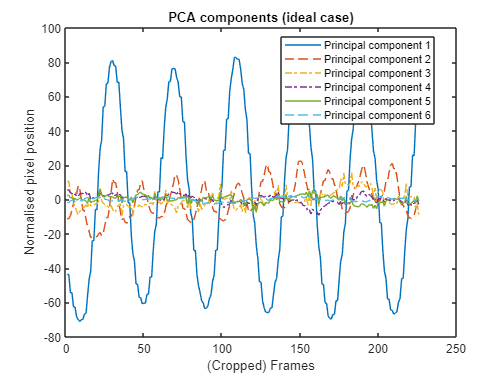

plot(Y(1,:))
title('PCA components (ideal case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')

hold on
plot(Y(2,:),'--')
plot(Y(3,:),'-.')
plot(Y(4,:),'-.')
plot(Y(5,:),'-')
plot(Y(6,:),'--')
legend('Principal component 1', ...
       'Principal component 2', ...
       'Principal component 3', ...
       'Principal component 4', ...
       'Principal component 5', ...
       'Principal component 6','Location','best')
hold off

### Plots PCA eigenvalues

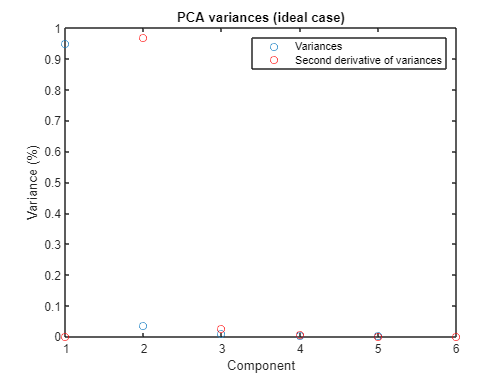

plot(lambda/sum(lambda), 'o')
title('PCA variances (ideal case)')
xlabel('Component')
ylabel('Variance (%)')

ddlambda = zeros(size(lambda));
for i = 1:length(lambda)
    if i == 1
        ddlambda(i) = 0;
    elseif i == length(lambda)
        ddlambda(i) = 0;
    else
        ddlambda(i) = (lambda(i+1) - 2*lambda(i) + lambda(i-1));
    end
end

hold on
plot(ddlambda/sum(abs(ddlambda)), 'ro')
legend('Variances','Second derivative of variances')
hold off

## Analysis

### Gets fast fourier transforms of largest principal components 

%%% Modified from fft documentation

Fs = 1;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = sz;             % Length of signal
t = (0:L-1)*T;        % Time vector

f_1 = fft(Y(1,:))

f_1 = 	1.0e+03 *

  -0.0000 + 0.0000i  -1.0142 - 0.3152i  -0.8826 - 0.3055i  -1.1532 - 0.2582i  -1.4858 - 0.4011i  -3.0912 - 2.2227i   4.7195 + 4.3070i   1.0720 + 1.1163i   0.6514 + 0.6837i   0.3427 + 0.4973i   0.2401 + 0.4863i   0.0661 + 0.2083i   0.0322 + 0.4494i   0.0324 + 0.3246i   0.0526 + 0.3017i   0.0114 + 0.2731i   0.0491 + 0.2371i  -0.0087 + 0.2455i  -0.0247 + 0.2135i  -0.0344 + 0.1928i  -0.0322 + 0.1965i   0.0003 + 0.1730i  -0.0462 + 0.1721i  -0.0186 + 0.1493i  -0.0295 + 0.1442i  -0.0545 + 0.1189i  -0.0418 + 0.1170i   0.0377 + 0.2437i   0.0071 + 0.1485i  -0.0231 + 0.1448i  -0.0286 + 0.1088i  -0.0228 + 0.1178i  -0.0315 + 0.0993i  -0.0349 + 0.1118i  -0.0173 + 0.0981i  -0.0671 + 0.1072i  -0.0473 + 0.0974i  -0.0516 + 0.0910i  -0.1055 + 0.1658i  -0.0353 + 0.1219i  -0.0222 + 0.0934i  -0.0541 + 0.0913i  -0.0569 + 0.0992i  -0.0394 + 0.0700i  -0.0774 + 0.0749i  -0.0503 + 0.0797i  -0.0436 + 0.0764i  -0.0674 + 0.0530i  -0.0331 + 0.0535i  -0.0340 + 0.0810i


f_2 = fft(Y(2,:))

f_2 = 	1.0e+03 *

   0.0000 + 0.0000i  -0.2630 + 0.6975i  -0.2546 + 0.1417i  -0.0108 + 0.4065i  -0.0965 + 0.1629i  -0.0900 + 0.1267i   0.1311 - 0.1802i   0.1377 - 0.0675i  -0.0783 - 0.1880i  -0.0022 - 0.1703i  -0.0379 - 0.2849i  -0.1595 - 1.0219i   0.0761 + 0.4429i   0.0206 + 0.1889i   0.0242 + 0.1004i   0.0529 + 0.0891i   0.0435 + 0.0237i  -0.1812 - 0.0857i  -0.0751 + 0.0867i  -0.0756 + 0.0987i  -0.0608 + 0.0651i  -0.0065 + 0.0867i  -0.0630 + 0.0785i   0.1261 - 0.0017i   0.0362 - 0.0061i  -0.0008 + 0.0004i   0.0292 + 0.0152i  -0.0159 + 0.0694i  -0.0295 + 0.1250i   0.0458 + 0.0151i   0.0292 + 0.0354i  -0.0007 + 0.0290i   0.0144 + 0.0381i   0.0022 + 0.0500i  -0.0772 + 0.0253i   0.0101 + 0.0257i   0.0089 + 0.0065i   0.0054 - 0.0008i   0.0226 + 0.0401i   0.0030 + 0.0077i  -0.0383 - 0.0209i  -0.0227 + 0.0088i  -0.0034 - 0.0091i  -0.0150 + 0.0061i   0.0056 + 0.0167i  -0.0105 + 0.0409i   0.0035 - 0.0000i  -0.0138 + 0.0189i  -0.0148 - 0.0035i  -0.0081 + 0.0148i


### Plot absolute values of the FFT

#### PC1

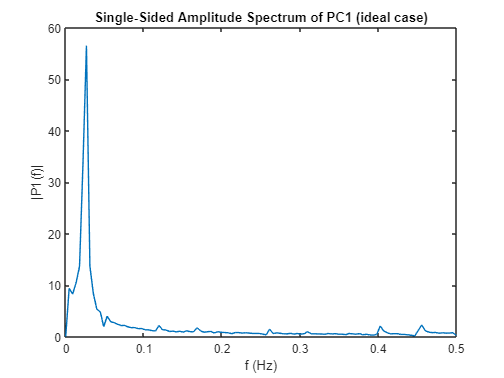

%%% Modified from fft documentation

P2_1 = abs(f_1/L);
P1_1 = P2_1(1:L/2+1);
P1_1(2:end-1) = 2*P1_1(2:end-1);

f1 = Fs*(0:(L/2))/L;
plot(f1,P1_1) 
title('Single-Sided Amplitude Spectrum of PC1 (ideal case)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


P1_1_max = max(P1_1)

P1_1_max = 56.5429

f1_max = f1(P1_1 == P1_1_max)

f1_max = 0.0265

### Use least square fitting to estimate sine waves for PCs (assuming simple harmonic motion)

#### PC1

%%% Minimise LSE: sum( abs( f(x_k)-y_k )^2 )
%%% Function: f(x) = A*sin(omega_n*x + phi)
x = 1:sz;
LSE_sin_1 = @(n) sum( abs( n(1)*sin(n(2)*x + n(3))-Y(1,:) ).^2 );
n0_1 = [P1_1_max, f1_max*2*pi, 0*(pi/180)];
coef_1 = fminsearch(LSE_sin_1,n0_1)

coef_1 =    71.9749    0.1566    3.2582


Error_1 = LSE_sin_1(coef_1)

Error_1 = 9.3115e+03

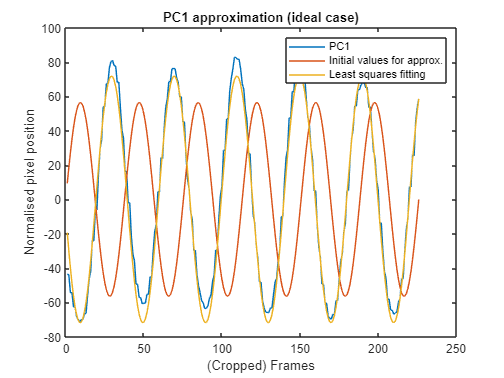


y_1 = coef_1(1)*sin(coef_1(2)*x + coef_1(3));
y0_1 = n0_1(1)*sin(n0_1(2)*x + n0_1(3));

plot(Y(1,:))
title('PC1 approximation (ideal case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_1)
plot(y_1)
legend('PC1','Initial values for approx.', 'Least squares fitting')
hold off

## Various functions are here:

### Imports data

function camData = importCamData(Dataset,Camera)

Data_path =join( ['C:' ...
    '\Users' ...
    '\dakin' ...
    '\Oscillating-Mass-and-Dimensionality-Reduction' ... 
    '\Project_Datasets' ...
    '\',Dataset, ... 
    '\',Camera] ); % Change to location of files

camData = load( Data_path );

end



### Shows cropped and uncropped video frame

%%% Shows cropped and uncropped video frame
function [im_1,im_2] = showFrames(frameNum,vidFrame,width,height)

normFrame = vidFrame(:,:,:,frameNum);
im_1 = image(normFrame);

croppedFrame = vidFrame(height,width,:,frameNum);
im_2 = image(croppedFrame);

end



### Finds pixel that corresponds to cap

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d)

if nargin == 4
    d = 10;
elseif nargin == 2
    x = 82;
    y = 198;
end


r = croppedFrame1(end-y,x,1);
g = croppedFrame1(end-y,x,2);
b = croppedFrame1(end-y,x,3);


cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));
end



### Finds the pixels that correspond to the cap using brightness

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixelsBright(croppedFrame,d)

if nargin == 1
    d = 10;
end

br = max( rgb2gray(croppedFrame) );

cap_Pixels = ((croppedFrame(:,:,1) >= br - d) & (croppedFrame(:,:,1) <= br + d)) ...
            &((croppedFrame(:,:,2) >= br - d) & (croppedFrame(:,:,2) <= br + d)) ...
            &((croppedFrame(:,:,3) >= br - d) & (croppedFrame(:,:,3) <= br + d));
end

### Finds the bounds for the cap pixels

%%% Finds the bounds for the cap pixels
function [top,bottom,left,right] = Boundaries(cap_Pixels)

top = 0;
bottom = 0;
left = 0;
right = 0;

sz_row = size(cap_Pixels,1);
for i = 1:sz_row
    findOne = size(find(cap_Pixels(i,:)));
    if findOne(2) ~= 0
        top = sz_row - i;
        break;
    end
end

for i = 1:sz_row
    findOne = size(find(cap_Pixels(end-i,:)));
    if findOne(2) ~= 0
        bottom = i;
        break;
    end
end

sz_col = size(cap_Pixels,2);
for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,i)));
    if findOne(1) ~= 0
        left = i;
        break;
    end
end

for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,end-i)));
    if findOne(1) ~= 0
        right = sz_col - i;
        break;
    end
end

end



### Finds centre from bounds

%%% Finds centre from bounds
function [x,y] = centre(top,bottom,left,right)

y = mean([top,bottom]);
x = mean([left,right]);

end



### Finds centre from averaging the number of pixels

%%% Finds centre from averaging the number of pixels
function [x,y] = centre_avg(cap_Pixels)
[sz_row,sz_col] = size(cap_Pixels);

x = 0;
x_num = 0;
for i = 1:sz_col
    x = x + sum(cap_Pixels(:,i))*i ;
    x_num = x_num + sum(cap_Pixels(:,i)) ;
end
x = x/x_num;

y = 0;
y_num = 0;
for i = 1:sz_row
    y = y + sum(cap_Pixels(i,:))*i ;
    y_num = y_num + sum(cap_Pixels(i,:)) ;
end
y = sz_row - y/y_num;

end



### Gets X and Y data from camera data

%%% Gets X and Y data from camera data
function [X,Y] = getXY(camData,width,height,x,y,d)

if nargin == 5
    d = 10;
elseif nargin == 3
    x = 82;
    y = 198;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);
croppedFrame1 = camData(height,width,:,1);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Gets X and Y data from camera data using brightness

%%% Gets X and Y data from camera data
function [X,Y] = getXYBright(camData,width,height,d)

if nargin == 3
    d = 10;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixelsBright(croppedFrame,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Plots X and Y on the same graph

%%% Plots X and Y on the same graph
function plotXY(X,Y,d,Dataset)

plot(X)
if nargin == 4
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (data = ',Dataset,', d = ',num2str(d),')']);
else
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (d = ',num2str(d),')']);
end
title(title_text)
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y)
legend('X','Y')
hold off

end



